load('benchmarkstability.mat');
load('stabilitycanshu.mat');

进行缩聚

index1 = [13,21,26,27,29];
index2 = [1:12,14:20,22:25,28];

Mm = M(index1,index1);
Mms = M(index1,index2);
Km = K(index1,index1);
Kms = K(index1,index2);
Ks = K(index2,index2);
Ksm = K(index2,index1);
Cm = C(index1,index1);
Cms = C(index1,index2);

Mmn = MNrt(index1,index1);
Mmsn = MNrt(index1,index2);
Kmn = KNrt(index1,index1);
Kmsn = KNrt(index1,index2);
Ksn = KNrt(index2,index2);
Ksmn = KNrt(index2,index1);
Cmn = CNrt(index1,index1);
Cmsn = CNrt(index1,index2);

KP = K-KNrt;
CP = C-CNrt;
MP = M-MNrt;

Mmp = MP(index1,index1);
Mmsp = MP(index1,index2);
Kmp = KP(index1,index1);
Kmsp = KP(index1,index2);
Ksp = KP(index2,index2);
Ksmp = KP(index2,index1);
Cmp = CP(index1,index1);
Cmsp = CP(index1,index2);

Kre = (Km-Kms*(Ks\Ksm));
Mre = (Mm-Mms*(Ks\Ksm));Mre(2,2) = 1e-2;Mre(5,5) = 1e-2;
Cre = (Cm-Cms*(Ks\Ksm));

Kren = (Kmn-Kmsn*(Ksn\Ksmn));
Mren = (Mmn-Mmsn*(Ksn\Ksmn));
Cren = (Cmn-Cmsn*(Ksn\Ksmn));

Krep = Kmp; % 物理子结构的自由度已经被包括在主自由度中了
Mrep = Mmp;
Crep = Cmp;

计算CR积分算法的$\alpha$

dt = 1/1024;
al = (4*Mre+2*dt*Cre+dt^2*Kre)\(4*Mre);

计算传递函数

P = 1.5;
I = 40;
D = 1e-8;
N = 1000;
s = tf('s');
%Gp0 = P+I/s+D*N/(1+N/s);
Gp0 = P+I/s+D*s;
Gp = [Gp0,0;0,Gp0];
Gps = ss(Gp);

然后是作动器传递函数G

%sys_ss = ss(A,B,C,D);
Gs = ss(A_cplant,B_cplant,C_cplant,D_cplant);
%G = tf(Gs);

计算Gp与G的传递函数

此处计算了很多G，最后只使用了G，因为离散的效果很不好，尝试了各种方法，methon里使用tustin、zpk形式再离散、使用状态空间方程ss形式进行离散、先计算再离散、先离散再计算，bode图来看，ss形式计算后再离散bode图效果比较好，但是很离谱的是，这个时候计算传递函数的零点就已经大于1了（因为我们最后需要的是零点），但是连续下实部都是小于0的，就很费解

%k1 = [0,1;1,0];
%G2 = zpk(G2);
%G1 = c2d(G2);
%G1 = k1*G1;
%G11 = c2d(G5,dt)
%G2 = (eye(2)+Gp*G)\Gp*G

%Gpd = c2d(Gp,dt,'tustin');
%Gd = c2d(G,dt,'tustin');
%sys_combined1 = series(Gpd, Gd);
%G3 = feedback(sys_combined1, eye(2));
%G4 = (eye(2)+Gpd*Gd)\Gpd*Gd;

%G1 = tf(G1);bode(G1,G2);bode(G1,G3);

sys_combined = series(Gps, Gs);
G5 = feedback(sys_combined, eye(2));
G1 = c2d(G5,dt);

划分主自由度和从自由度

根据benmark模型来看，外力作用在每一层的横向位移上，故主自由度定义为每层的横向位移Xm，其余定义为从自由度Xs


$$X=\left\lbrack \begin{array}{c}
X_m \\
X_s 
\end{array}\right\rbrack$$


离散情况下

在计算过程中需要得到反力，反力计算在benchmark中需要扩展到5维

此处区分两种情况：

1.以缩聚后的矩阵求解，这样输入2，无法得到3个输出

2.以benchmark里的5dof状态求解，这样得到5输出取3

综合考虑，选择2，计算反力如下

k1 = zeros(5,2);
k1(1,1) = 1;
k1(2,2) = 1;
k2 = zeros(5,3);
k2(3,1) = 1;
k2(4,2) = 1;
k2(5,3) = 1;

k4 = k1-k2*inv(Koo)*Kot;

k3 = zeros(5,5);
k3(4,1) = 1;
k3(2,2) = 1;
k3(5,3) = 1;

k6 = zeros(2,5);
k6(1,4) = 1;
k6(2,2) = 1;
M5 = k3*M_phys_5dof*k4;
C5 = k3*C_phys_5dof*k4;
K5 = k3*K_phys_5dof*k4;

G1 = tf(G1);
G1 = G1*k6;
fm = M5*G1*(z-1)^2*(al\(dt^2*z*eye(5)))+C5*G1*(z-1)/(z*dt)+K5*G1;

%传递函数,如果是连续时间会怎样
s = tf('s');
s2 = s^2;
G5s = tf(G5);
Gcl1s = Mren*s^2+Cren*s+Kren;
%Gcl1s = series(Mren,ss(s2))+series(Cren,ss(s))+Kren;
fms = M5*G5s*k6*s^2+C5*G5s*k6*s+K5*G5s*k6;
%fms = series(series(M5,series(series(k6,s),G5)+series(series(C5,G5),series(k6,s))+series(series(K5,G5),k6);

Gcl3s = Gcl1s+fms;
%Gcl3ss = parallel(Gcl1s,fms);
%Gcl3s = tf(Gcl3ss);

[num,den] = tfdata(Gcl3s, 'v');
sym x;
x = sym('x');
Gcl4s = x*ones(5);
for d1 = 1:5
    for d2 = 1:5
        Polynum = poly2sym(num(d1,d2), x);
        Polyden = poly2sym(den(d1,d2), x);
        Gcl4s(d1,d2) = Polynum/Polyden;
    end
end

detGs = vpa((det(Gcl4s)),50);
solGs = solve(detGs);
max(real(solGs))

$$ans = -0.37058067932838762211181064248551$$

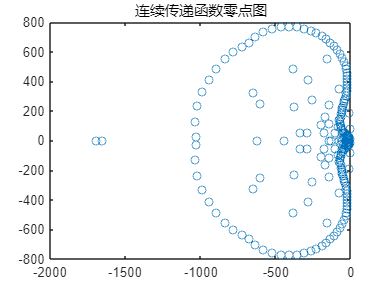

figure;
plot(real(solGs),imag(solGs),'o');
title('连续传递函数零点图')

l = 0;
j = 0;
z = tf('z',dt);

Gcl1 = (Mren*(z-1)^2)*(al\(dt^2*z*eye(5)))+Cren*(z-1)/(z*dt)+Kren;
%fm = z^(-l)*(Crep*k1*G1(2,2)*(z-1)/(z*dt))+z^(-j)*(Krep*k1*G1(2,2));
Gcl3 = Gcl1+fm;
Gcl3 = minreal(Gcl3);
Gcl3 = simplify(Gcl3)

Gcl3 =
 
  从输入 1 到输出...
       0.01096 z^4 - 0.02192 z^3 + 0.01096 z^2 + 7.529e07 z - 3.674e07
   1:  ---------------------------------------------------------------
                                      z
 
       2.028e-07 z^23 - 2.651e-06 z^22 + 1.959e06 z^21 - 3.342e07 z^20 + 2.717e08 z^19 - 1.399e09 z^18 + 5.124e09 z^17 - 1.419e10 z^16 + 3.082e10 z^15 - 5.384e10 z^14 + 7.687e10 z^13 - 9.064e10 z^12 + 8.885e10 z^11 - 7.262e10 z^10 + 4.949e10 z^9 - 2.804e10 z^8 + 1.312e10 z^7 - 5.013e09 z^6 + 1.54e09 z^5 - 3.709e08 z^4 + 6.749e07 z^3 - 8.722e06 z^2 + 7.132e05 z - 2.773e04
   2:  ------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
                                            

%max(abs(tzero(Gcl3)))

计算行列式需要转成sym形式，传递函数形式无法det

[num,den] = tfdata(Gcl3, 'v');
sym x;
x = sym('x');
Gcl4 = x*ones(5);
%Gcl3 = c2d(Gcl3s,dt,'tustin');
for d1 = 1:5
    for d2 = 1:5
        Polynum = poly2sym(num(d1,d2), x);
        Polyden = poly2sym(den(d1,d2), x);
        Gcl4(d1,d2) = Polynum/Polyden;
    end
end

detG = vpa((det(Gcl4)),12);
solG = solve(detG == 0,x);
Gzero1= max(abs(solG))

$$Gzero1 = 2766905239428446.5073049636754041$$

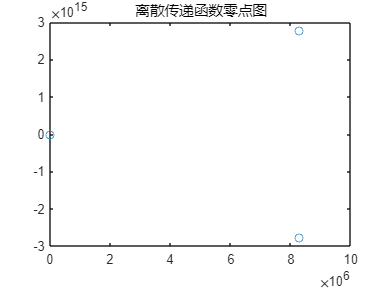

figure;
plot(real(solG),imag(solG),'o');
title('离散传递函数零点图')

%z = tf('z',dt);
%Gzero = zeros(50);
%for l = 1:50
%    for j = 1:50
%Gcl1 = (Mren+Mrep*G1(2,2))*(z-1)^2*(al\(dt^2*z*eye(3)))+Cren*(z-1)/(z*dt)+Kren;
%fm = z^(-l)*(Crep*G1(2,2)*(z-1)/(z*dt))+z^(-j)*(Krep*G1(2,2));
%Gcl3 = Gcl1+fm;
%Gzero(l,j) = max(abs(zero(Gcl3)));
%    end
%end